# [Sonar Detection](http://apmonitor.com/pds/index.php/Main/SonarDetection)

Sonar (sound navigation and ranging) uses sound waves to detect objects, similar to how a bat uses echo-location to navigate, and detect objects. It is the same principle with seismic data for non-invasive underground exploration of geologic formations to locate oil or gas reserves.

**Background:** A data set of sonar returns is available for rock and metal pipe with samples taken from different angles and locations. The data was collected in a laboratory under controlled conditions as a case study for detecting underground pipe. There are 111 labeled sets for the metal cylinder (pipe) and 97 sonar patterns from rocks with similar conditions. Each sample is a set of 60 numbers between 0 and 1 that represents the integrated energy within a distinct frequency band and for a given time period.

Although this case study is specific to detecting differences between metal pipe and rock, it is similar to detection of other underground features such as tunnels, mines, aquifers, and fluid-filled pipelines.

This case study focuses on classification using the 60 attributes (sonar returns) to determine whether object is rock or a metal pipe. The label associated with each record contains the letter *R* if the object is a rock and *M* if it is a metal pipe. [**One-hot encoding**](https://en.wikipedia.org/wiki/One-hot) is needed to translate this character label into a binary representation (1 or 2) for classification.

url = 'http://apmonitor.com/pds/uploads/Main/sonar_detection.txt';
data = readtable(url);

% One-hot encode 'Class' (2 is 'Metal', 1 is 'Rock')
data.Class = categorical(data.Class, {'R', 'M'}, {'1', '2'});
data.Class = double(data.Class);

# Answer

## Classification: Detect Pipe or Rock with Sonar Data

Classification of Rock or Mine with [sonar data](https://archive.ics.uci.edu/ml/datasets/Connectionist+Bench+(Sonar,+Mines+vs.+Rocks)). Sonar (sound navigation and ranging) uses sound waves to detect objects, similar to how a bat uses echo-location to navigate, and detect objects. It is the same principle with seismic data for non-invasive underground exploration of geologic formations to locate oil or gas reserves.

`url` `=` `'https://apmonitor.com/pds/uploads/Main/sonar_detection.txt'`

The data set of sonar is taken from different angles and locations to detect the rock or pipe. The data was collected in a laboratory under controlled conditions as a case study for detecting underground pipe. There are 111 labeled sets for the metal cyclinder (pipe) and 97 sonar patterns from rocks with similar conditions. Each sample is a set of 60 numbers between 0 and 1 that represents the integrated energy within a distinct frequency band and for a given time period.

[Pipe / Rock Sonar Case Study](https://apmonitor.com/pds/index.php/Main/SonarDetection) on [Machine Learning for Engineers](https://apmonitor.com/pds/index.php/Main/SonarDetection)

Although this case study is specifc to detecting differences between metal pipe and rock, it is similar to detection of other underground features such as tunnels, mines, aquifers, and fluid-filled pipelines.

**Read Data**

Read data with `data=readtable(url)`

`Display 10 random rows with datasample(data,10)`

data = readtable('http://apmonitor.com/pds/uploads/Main/sonar_detection.txt')

data = 208×61 table
     Ang1      Ang2      Ang3      Ang4      Ang5      Ang6      Ang7      Ang8      Ang9     Ang10     Ang11     Ang12     Ang13     Ang14     Ang15     Ang16     Ang17     Ang18     Ang19     Ang20     Ang21     Ang22     Ang23     Ang24     Ang25     Ang26     Ang27     Ang28     Ang29     Ang30     Ang31     Ang32     Ang33     Ang34     Ang35     Ang36     

disp(datasample(data,10))

     Ang1      Ang2      Ang3      Ang4      Ang5      Ang6      Ang7      Ang8      Ang9     Ang10     Ang11     Ang12     Ang13     Ang14     Ang15     Ang16     Ang17     Ang18     Ang19     Ang20     Ang21     Ang22     Ang23     Ang24     Ang25     Ang26     Ang27     Ang28     Ang29     Ang30     Ang31     Ang32     Ang33     Ang34     Ang35     Ang36     Ang37  

**Data Visualization**

figure('Position', [0, 0, 1200, 800]);

%remove "Class" from the data set
datanoclass= data(:,1:60)

datanoclass = 208×60 table
     Ang1      Ang2      Ang3      Ang4      Ang5      Ang6      Ang7      Ang8      Ang9     Ang10     Ang11     Ang12     Ang13     Ang14     Ang15     Ang16     Ang17     Ang18     Ang19     Ang20     Ang21     Ang22     Ang23     Ang24     Ang25     Ang26     Ang27     Ang28     Ang29     Ang30     Ang31     Ang32     Ang33     Ang34     Ang35     Ang36  

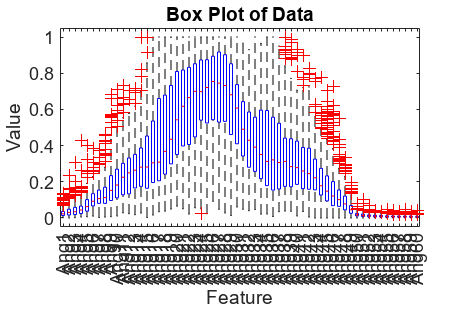

boxplot(table2array(datanoclass), 'Labels', data.Properties.VariableNames(1:60), 'Whisker', 1.5);
title('Box Plot of Data');
xlabel('Feature');
ylabel('Value');

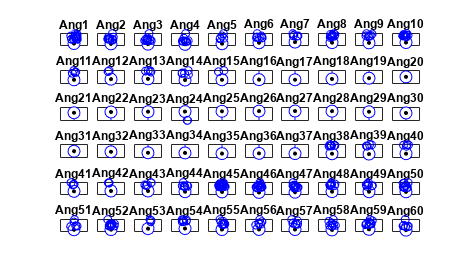

% Configure the subplots
num_subplots = size(datanoclass, 2);
rows = 6;
cols = 10;

% Loop through the subplots and add box plots
for i = 1:num_subplots
    subplot(rows, cols, i);
    boxplot(datanoclass{:, i}, 'Whisker', 1.5, 'PlotStyle', 'compact');
    title(datanoclass.Properties.VariableNames{i}, 'FontSize', 6);
    set(gca, 'XTick', []);
    set(gca, 'YTick', []);
end

% Adjust the figure layout and display the plot
set(gcf, 'PaperPositionMode', 'auto');
set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0, 1, 1]);

class_sizes = groupsummary(data,"Class");
disp(class_sizes)

    Class    GroupCount
    _____    __________

    {'M'}       111    
    {'R'}        97    



counts = categorical(class_sizes.Class)

counts = 2×1 categorical array
     M 
     R 


bar(counts,class_sizes.GroupCount);
title('Class Counts');
xlabel('Class');
ylabel('Count');

## Correlation Matrix

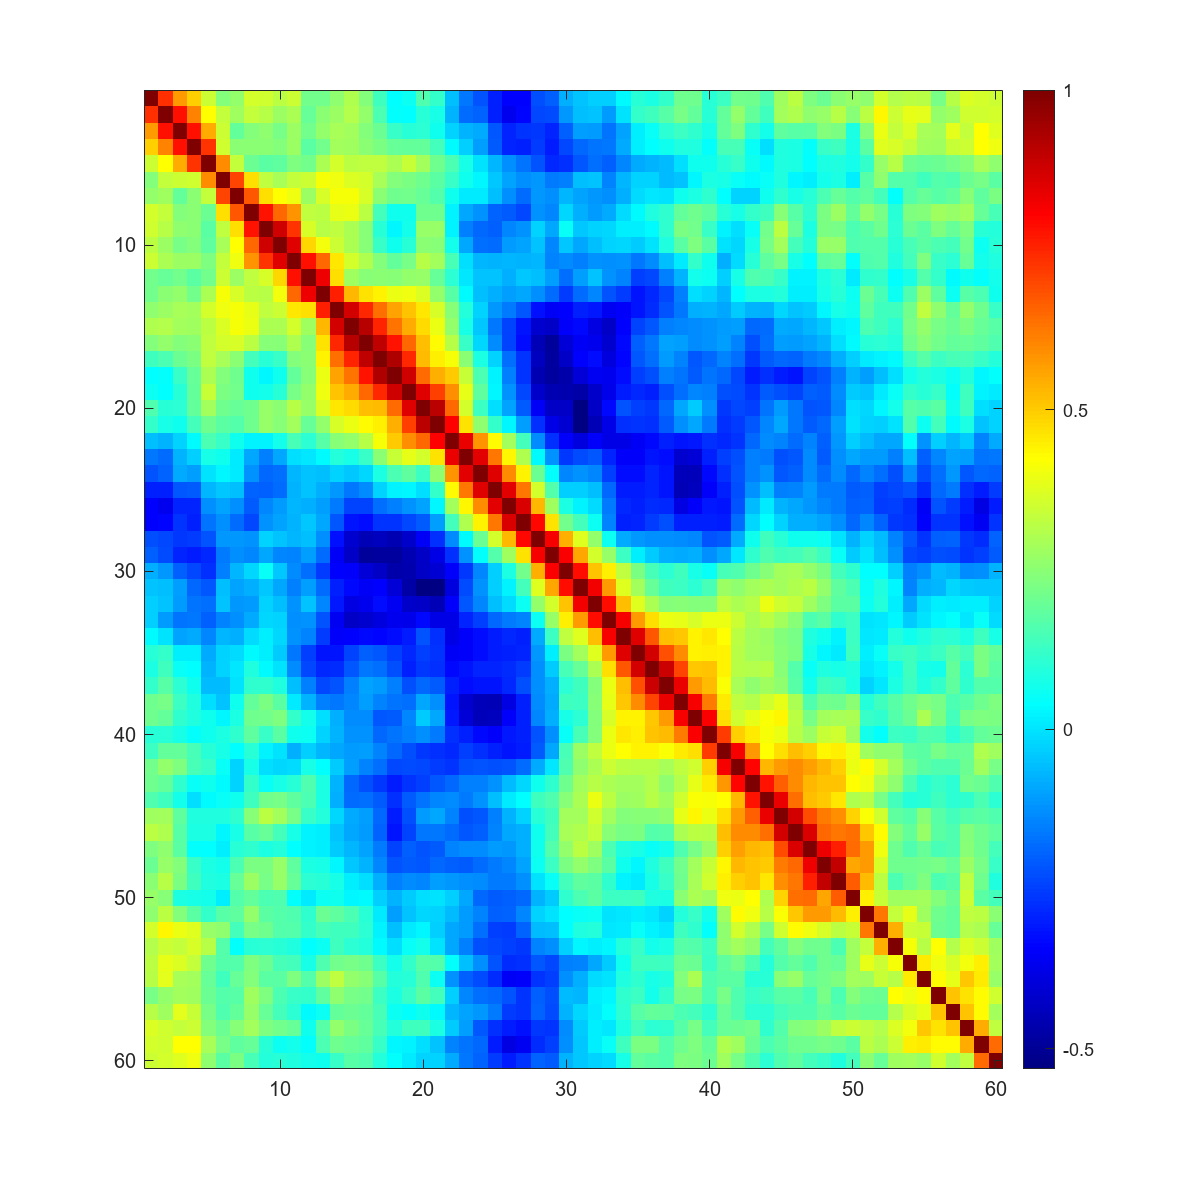

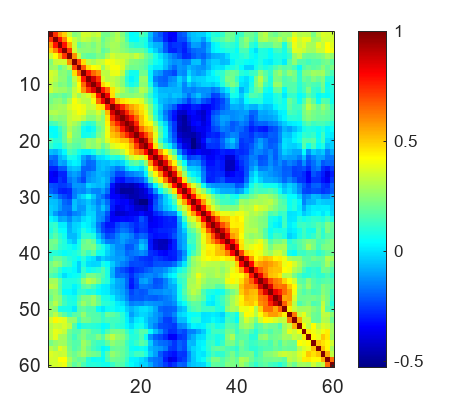

% Calculate the correlation matrix
corr_matrix = corr(table2array(data(:,1:60)));

% Create the figure and the axis object
fig = figure();
ax = axes();

% Plot the correlation matrix using the 'image' function
image(corr_matrix, 'CDataMapping', 'scaled', 'Parent', ax);

% Set the axis limits and the colormap
ax.XLim = [0.5 size(corr_matrix, 2) + 0.5];
ax.YLim = [0.5 size(corr_matrix, 1) + 0.5];
colormap('jet');

% Add a colorbar and set the figure size
colorbar();
fig.Position(3:4) = [800 800];

% Save the figure and show it
saveas(fig, 'sonar_correlation.png');

What insights do you gain from the data visualization and exploration? In particular, comment on the presence of uniform data distributions, outliers, missing data, and other data quality issues.

**Scale Data**

Scale data with a [Standard Scalar](https://scikit-learn.org/stable/modules/generated/sklearn.preprocessing.StandardScaler.html) so that all features (sonar returns) are scaled.

X = table2array(data(:,1:end-1));


% Standardize data
X = (X - mean(X)) ./ std(X);


% Convert back to table and set column names
data_std = array2table(X,"VariableNames",data.Properties.VariableNames(:,1:end-1));

**Best Features**

What are the factors that are most correlated or influential for predicting pipe versus rock. Manually produce a ranked list.

k = 5;
y = data.Class

y = 208×1 cell array
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}
    {'R'}


X_scores = fscmrmr(X, y); % Rank features by mutual information and redundancy measures
[~, idx] = sort(X_scores, 'descend');
k_best = X(:, idx(1:k)); % Select the top k features

column_names = data_std.Properties.VariableNames;
for i = 1:k
    fprintf('%s\n', column_names{idx(i)})
end

Ang30
Ang23
Ang29
Ang31
Ang25


# gives different Features, problem?

column_names2 = categorical(data_std.Properties.VariableNames)

column_names2 = 1×60 categorical array
     Ang1      Ang2      Ang3      Ang4      Ang5      Ang6      Ang7      Ang8      Ang9      Ang10      Ang11      Ang12      Ang13      Ang14      Ang15      Ang16      Ang17      Ang18      Ang19      Ang20      Ang21      Ang22      Ang23      Ang24      Ang25      Ang26      Ang27      Ang28      Ang29      Ang30      Ang31      Ang32      Ang33      Ang34      Ang35      Ang36      Ang37      Ang38      Ang39      Ang40      Ang41      Ang42      Ang43      Ang44      Ang45      Ang46      Ang47      Ang48      Ang49      Ang50      Ang51      Ang52      Ang53      Ang54      Ang55      Ang56      Ang57      Ang58      Ang59      Ang60 


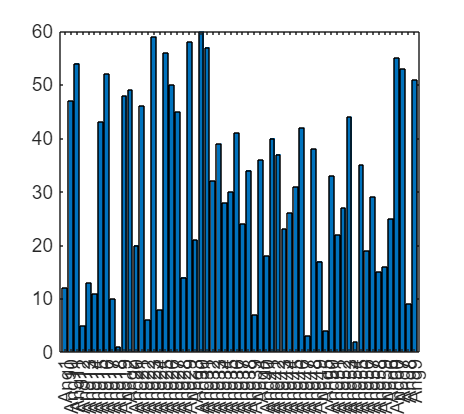

bar(column_names2,X_scores)

#  Need to add column names to results


[sorted_scores, idx] = sort(X_scores)

sorted_scores =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


idx =     18    54    47     5    12    22    39    24     8    17    14     1    13    28    58    59    49    40    56    20     3    51    43    37     6    44    52    34    57    35    45    32    50    38    55     4    42    48    33    41    36    46    15    53    27    21    10    19     2    26


dfscores= X_scores(1,1:10)

dfscores =     12    49    21    36     4    25    53     9    51    47


Result = array2table(dfscores)

Result = 1×10 table
    dfscores1    dfscores2    dfscores3    dfscores4    dfscores5    dfscores6    dfscores7    dfscores8    dfscores9    dfscores10
    _________    _________    _________    _________    _________    _________    _________    _________    _________    __________

       12           49           21           36            4           25           53            9           51            47    


**Train / Test Split**[**¶**](http://localhost:8888/notebooks/Downloads/Sonar_Detection_Solution.ipynb#Train-/-Test-Split)

Split the data into **Test** and **Train** sets. Randomly select values that split the data into a train (80%) and test (20%) set.

p=.2

p = 0.2000

%c= cvpartition (data, 'HoldOut',p)
[trainInd,valInd,testInd] = dividerand (height(data),0.8,0,0.2)

trainInd =      3     4     5     6     7     8     9    10    11    13    14    15    16    17    18    21    23    24    25    27    29    30    31    32    33    34    35    36    38    39    40    42    43    44    45    47    49    50    51    52    53    54    55    56    57    58    59    60    61    62



valInd =

  1×0 empty double row vector



testInd =      1     2    12    19    20    22    26    28    37    41    46    48    63    64    69    70    71    92    94    99   108   110   112   122   124   129   134   136   146   148   150   162   171   175   176   181   185   194   202   204   205   206


X_train= data(trainInd,:)

X_train = 166×61 table
     Ang1      Ang2      Ang3      Ang4      Ang5      Ang6      Ang7      Ang8      Ang9     Ang10     Ang11     Ang12     Ang13     Ang14     Ang15     Ang16     Ang17     Ang18     Ang19     Ang20     Ang21     Ang22     Ang23     Ang24     Ang25     Ang26     Ang27     Ang28     Ang29     Ang30     Ang31     Ang32     Ang33     Ang34     Ang35     Ang36     <

X_test = data(testInd,:)

X_test = 42×61 table
     Ang1      Ang2      Ang3      Ang4      Ang5      Ang6      Ang7      Ang8      Ang9     Ang10     Ang11     Ang12     Ang13     Ang14     Ang15     Ang16     Ang17     Ang18     Ang19     Ang20     Ang21     Ang22     Ang23     Ang24     Ang25     Ang26     Ang27     Ang28     Ang29     Ang30     Ang31     Ang32     Ang33     Ang34     Ang35     Ang36     

 Classification: Use 8 classification methods. 

Methods and documentation can be found at [https://www.mathworks.com/help/stats/classification.html](https://www.mathworks.com/help/stats/classification.html)

The Classification Learner app can also be used. Access it from the "Apps" tab in MATLAB or open it by running "classificationLearner" in your code

%Naive Bayes
nb= fitcnb(data, 'Class')

nb =   ClassificationNaiveBayes
            PredictorNames: {1×60 cell}
              ResponseName: 'Class'
     CategoricalPredictors: []
                ClassNames: {'M'  'R'}
            ScoreTransform: 'none'
           NumObservations: 208
         DistributionNames: {1×60 cell}
    DistributionParameters: {2×60 cell}


  Properties, Methods


crossval(nb)

ans =   ClassificationPartitionedModel
    CrossValidatedModel: 'NaiveBayes'
         PredictorNames: {1×60 cell}
           ResponseName: 'Class'
        NumObservations: 208
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: {'M'  'R'}
         ScoreTransform: 'none'


  Properties, Methods


resubLoss(nb)

ans = 0.2692


%Nearest Neighbors
fitcknn(data,'Class',Holdout=p)

ans =   ClassificationPartitionedModel
    CrossValidatedModel: 'KNN'
         PredictorNames: {1×60 cell}
           ResponseName: 'Class'
        NumObservations: 208
                  KFold: 1
              Partition: [1×1 cvpartition]
             ClassNames: {'M'  'R'}
         ScoreTransform: 'none'


  Properties, Methods





%Classification Tree
fitctree(data,'Class','Holdout',p)

ans =   ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {1×60 cell}
           ResponseName: 'Class'
        NumObservations: 208
                  KFold: 1
              Partition: [1×1 cvpartition]
             ClassNames: {'M'  'R'}
         ScoreTransform: 'none'


  Properties, Methods


%Discriminant Analysis
fitcdiscr(data, 'Class','Holdout',p)

ans =   ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {1×60 cell}
           ResponseName: 'Class'
        NumObservations: 208
                  KFold: 1
              Partition: [1×1 cvpartition]
             ClassNames: {'M'  'R'}
         ScoreTransform: 'none'


  Properties, Methods


%Support Vector Machine Classification
fitcsvm(data,'Class','Holdout',p)

ans =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {1×60 cell}
           ResponseName: 'Class'
        NumObservations: 208
                  KFold: 1
              Partition: [1×1 cvpartition]
             ClassNames: {'M'  'R'}
         ScoreTransform: 'none'


  Properties, Methods


%Classification Ensemble
fitcensemble(data,'Class','Holdout',p)

ans =   ClassificationPartitionedEnsemble
    CrossValidatedModel: 'LogitBoost'
         PredictorNames: {1×60 cell}
           ResponseName: 'Class'
        NumObservations: 208
                  KFold: 1
              Partition: [1×1 cvpartition]
      NumTrainedPerFold: 100
             ClassNames: {'M'  'R'}
         ScoreTransform: 'none'


  Properties, Methods


%Neural Network
fitcnet(data,'Class','Holdout',p)

ans =   ClassificationPartitionedModel
    CrossValidatedModel: 'NeuralNetwork'
         PredictorNames: {1×60 cell}
           ResponseName: 'Class'
        NumObservations: 208
                  KFold: 1
              Partition: [1×1 cvpartition]
             ClassNames: {'M'  'R'}
         ScoreTransform: 'none'


  Properties, Methods


%Generalized Additive Model
fitcgam(data,'Class','Holdout',p)

ans =   ClassificationPartitionedGAM
    CrossValidatedModel: 'GAM'
         PredictorNames: {1×60 cell}
           ResponseName: 'Class'
        NumObservations: 208
                  KFold: 1
              Partition: [1×1 cvpartition]
      NumTrainedPerFold: [1×1 struct]
             ClassNames: {'M'  'R'}
         ScoreTransform: 'logit'


  Properties, Methods



%Uncomment below to open the Classification Learner app
%classificationLearner